# DC Microgrid Simulator

clear all
close all
clc

rng(7)

numOfDGs = 5;
threshold = 0.6;

## Generate a random physical topology

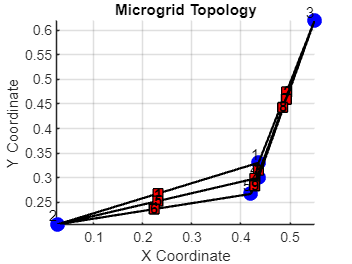

Coordinates of DGs:
    0.4360    0.3303
    0.0259    0.2046
    0.5497    0.6193
    0.4353    0.2997
    0.4204    0.2668

Adjacency Matrix:
     0     1     1     1     1
     1     0     0     1     1
     1     0     0     1     1
     1     1     1     0     1
     1     1     1     1     0

B_il Matrix:
     1     1     1     1     0     0     0     0     0
    -1     0     0     0     1     1     0     0     0
     0    -1     0     0     0     0     1     1     0
     0     0    -1     0    -1     0    -1     0     1
     0     0     0    -1     0    -1     0    -1    -1



coords =     0.4360    0.3303
    0.0259    0.2046
    0.5497    0.6193
    0.4353    0.2997
    0.4204    0.2668


A_ij =      0     1     1     1     1
     1     0     0     1     1
     1     0     0     1     1
     1     1     1     0     1
     1     1     1     1     0


B_il =      1     1     1     1     0     0     0     0     0
    -1     0     0     0     1     1     0     0     0
     0    -1     0     0     0     0     1     1     0
     0     0    -1     0    -1     0    -1     0     1
     0     0     0    -1     0    -1     0    -1    -1


% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
% R0 = 0.02;      % Resistance
% L0 = 0.01;      % Inductance
% C0 = 0.0022;    % Capacitance
% RL0 = 0.3;      % Load Resistance
% Y0 = 1/RL0;     % Load Conductance

R0 = 0.05;      % Resistance
L0 = 100e-6;      % Inductance
C0 = 10e-3;    % Capacitance
RL0 = 1;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance

for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
% Rl0 = 0.02;     % Line Resistance
% Ll0 = 0.01;     % Line Inductance

Rl0 = 0.1;     % Line Resistance
Ll0 = 100e-6;     % Line Inductance
numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 
 global DG Line B_il A_ij

## Co-Design Process

parameters


BarGamma = 1;    % Fixed value for gammaBar
isSoft = 1; % Set to 1 to avoid the hard graph constraint

pScalar = 1/(numOfDGs+numOfLines)

pScalar = 0.0714


% piVals = 0.2;
% plVals = 0.16;

piVals = pScalar*ones(1,numOfDGs);
plVals = pScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusLocalController = logical
   0


DG{1}

ans = struct with fields:
              R: 0.0562
              L: 0.0054
              C: 0.0101
              Y: 0.9949
              A: [3×3 double]
              B: [3×1 double]
    coordinates: [0.4360 0.3303]
             P0: [3×3 double]
             K0: [-6.8699e+03 -1.0683e+04 -1.3138e+04]
             nu: 1.8062e-18
            rho: 6.1633e+16
    gammaTilde0: 4.3595e-06


% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

## 2. Global Controller Design

[DG,Line,statusGlobalController,gammaTildeVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)

DG = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusGlobalController = logical
   1


gammaTildeVal = 3.0418e-09

DG{1}.K{1,1}

ans = 1.0e+16 *

         0         0         0
         0   -1.0424         0
         0         0         0


DG{1}.K{1,2}

ans =      0     0     0
     0     0     0
     0     0     0


Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

Optimize pVals (Method 2: Use Matlab 'fmincon')

[piVals, plVals] = optimizeCodesignParameters()

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.01            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 87              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 268             
  Matrix variables       : 19 (scalarized: 282)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 5
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pr

DG1 = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


Line1 = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


statusL = logical
   0


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      15    1.000000e+06    0.000e+00    0.000e+00

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

piVals =     0.2000    0.2000    0.2000    0.2000    0.2000


plVals =     0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111
